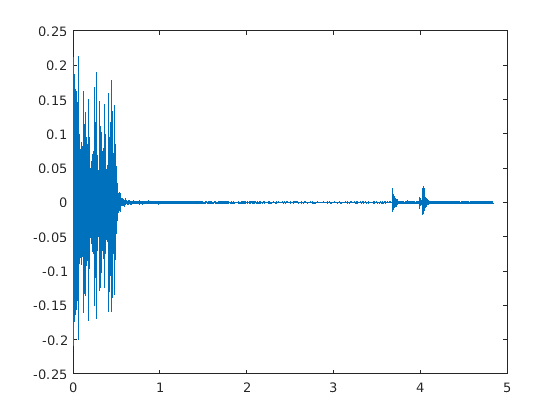

load('short_modem_rx.mat')
start_idx = find_start_of_signal(y_r, x_sync);
y_t = y_r(start_idx+length(x_sync):end);
t = 0:(1/Fs):(length(y_t)-1)/Fs;
plot(t,y_t)

soundsc(y_t,Fs)

cosine_function = cos(2*pi*f_c*t);
Cosine_Function = fft(cosine_function);
Y_t = fft(y_t);

Y_c = conv(cosine_function,Y_t);

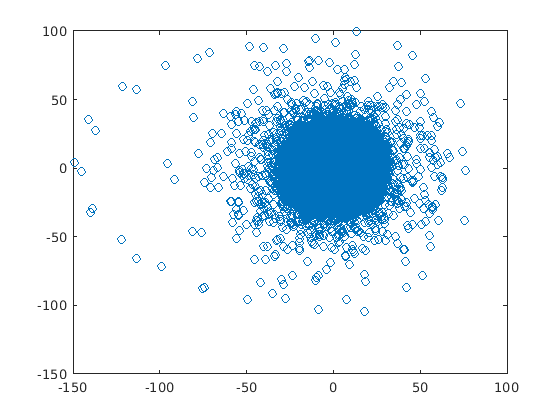

plot(Y_c,'o')